# Figures of average acoustic features per bat

Playing around with all experimental dates manually checked so far

BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
LocalDataDir = '/Users/elie/Documents/DeafBats/Data';

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'), 'MicAudioGood','CallType','OnSetOffsetSample',...
    'TmicAll','BatID', 'Duration','RMS_mean','Sal_mean',...
    'F0_mean','F0_cv','Spect_mean','Spect_std','Spect_kurt','Spect_skew','Spect_ent',...
    'Time_mean','Time_std','Time_kurt','Time_skew','Time_ent','SpectralMean_mean','Q1_mean','Q2_mean','Q3_mean','SpectMic_mean','SpectMic_std',...
    'SpectMic_kurt','SpectMic_skew','SpectMic_ent','Q1Mic_mean','Q2Mic_mean','Q3Mic_mean', 'AmpPeriodF','AmpPeriodP')
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);
DurationElmt = diff(OnSetOffsetSample,1,2)/192000*1000;
fprintf(1,'In total, there are %d Vocal elements, %d are also of good microphone quality\n', length(MicAudioGood01), sum(MicAudioGood01))

In total, there are 36227 Vocal elements, 28091 are also of good microphone quality


Get color vectors ready

% Get the color vector ready for call type
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UCT = unique(CallType(~cellfun(@isempty, CallType)));
UCT = UCT([1:4 9 5:8 10:14])

UCT = 14×1 cell array
    {'BB' }
    {'Ba' }
    {'Bu' }
    {'Ch' }
    {'Pi' }
    {'LPi'}
    {'LT' }
    {'PB' }
    {'Pa' }
    {'Ra' }
    {'SB' }
    {'Sq' }
    {'Tr' }
    {'Un' }


UCTFull = UCT;
UCTFull{strcmp(UCT, 'Tr')} = 'Trill';
UCTFull{strcmp(UCT, 'Ba')} = 'Bark';
UCTFull{strcmp(UCT, 'Pi')} = 'Pitchy Call';
UCTFull{strcmp(UCT, 'LPi')} = 'Loud Pitchy Call';
UCTFull{strcmp(UCT, 'Bu')} = 'Low Buzz';
UCTFull{strcmp(UCT, 'Pa')} = 'Panting';
UCTFull{strcmp(UCT, 'LT')} = 'Low Tuck';
UCTFull{strcmp(UCT, 'Sq')} = 'Squeal';
UCTFull{strcmp(UCT, 'Ra')} = 'Rattle';
UCTFull{strcmp(UCT, 'Ch')} = 'Chuckles';
UCTFull{strcmp(UCT, 'BB')} = 'Bark Buzz';
UCTFull{strcmp(UCT, 'PB')} = 'Pitchy Call Buzz';
UCTFull{strcmp(UCT, 'SB')} = 'Squeal Buzz';
UCTFull{strcmp(UCT, 'Un')} = 'Unknown';
CCT = nan(length(CallType),3);
IndNoCall = cellfun(@isempty, CallType);
CallType(IndNoCall) = {'Un'};
for ct=1:length(UCT)
    CCT(contains(CallType,UCT(ct)),:) = repmat(ColorCode(ct,:),sum(contains(CallType,UCT(ct))),1);
end

% Get the color vector ready for BatName, Sex and Deafness
GGPath = dir('/Users/elie/Google Drive*');
Path2RecordingTable = fullfile(GGPath.folder, GGPath.name,'My Drive/JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Saline Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Kanamycin Female';
    end

end
USexDeaf = {'Kanamycin Male' 'Saline Male' 'Kanamycin Female' 'Saline Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

Construct the table of PAF for statistical purposes

Tbl =  table(BatID, CallType, Sex,Deaf,DurationElmt,RMS_mean,...
    Sal_mean,F0_mean/1000,F0_cv, Spect_mean/10^3,Spect_std/10^3,Spect_kurt,Spect_skew,Spect_ent,...
    Time_mean,Time_std,Time_kurt,Time_skew,Time_ent,Q1_mean/10^3,...
    Q2_mean/10^3,Q3_mean/10^3,SpectMic_mean/10^3,SpectMic_std/10^3,...
    SpectMic_kurt,SpectMic_skew,SpectMic_ent,Q1Mic_mean/10^3,Q2Mic_mean/10^3,Q3Mic_mean/10^3, AmpPeriodF,AmpPeriodP,...
    'VariableNames', {'BatID', 'CT','Sex','HorD',...
    'Duration (ms)','RMS mean','Saliency (AU)','F0 (kHz)','F0 CV','Spectral mean (kHz)','Spectral std (kHz)','Spectral kurtosis (Hz)','Spectral skewness (Hz)','Spectral entropy',...
    'Time mean (ms)','Time std (ms)','Time kurtosis (ms)','Time skewness (ms)','Time entropy','First quartile (kHz)','Second quartile (kHz)','Third quartile (kHz)','Mic Spectral mean (kHz)','Mic Spectral std (kHz)',...
    'Mic Spectral kurtosis (Hz)','Mic Spectral skewness (Hz)','Mic Spectral entropy','Mic First quartile (kHz)','Mic Second quartile (kHz)','Mic Third quartile (kHz)','Amplitude Periodicity F (Hz)','Amplitude Periodicity P'});
Tbl.HorD = categorical(Tbl.HorD, {'H' 'D'});

Go through all acoustic categories and calculate and plot the average values of features for all individuals

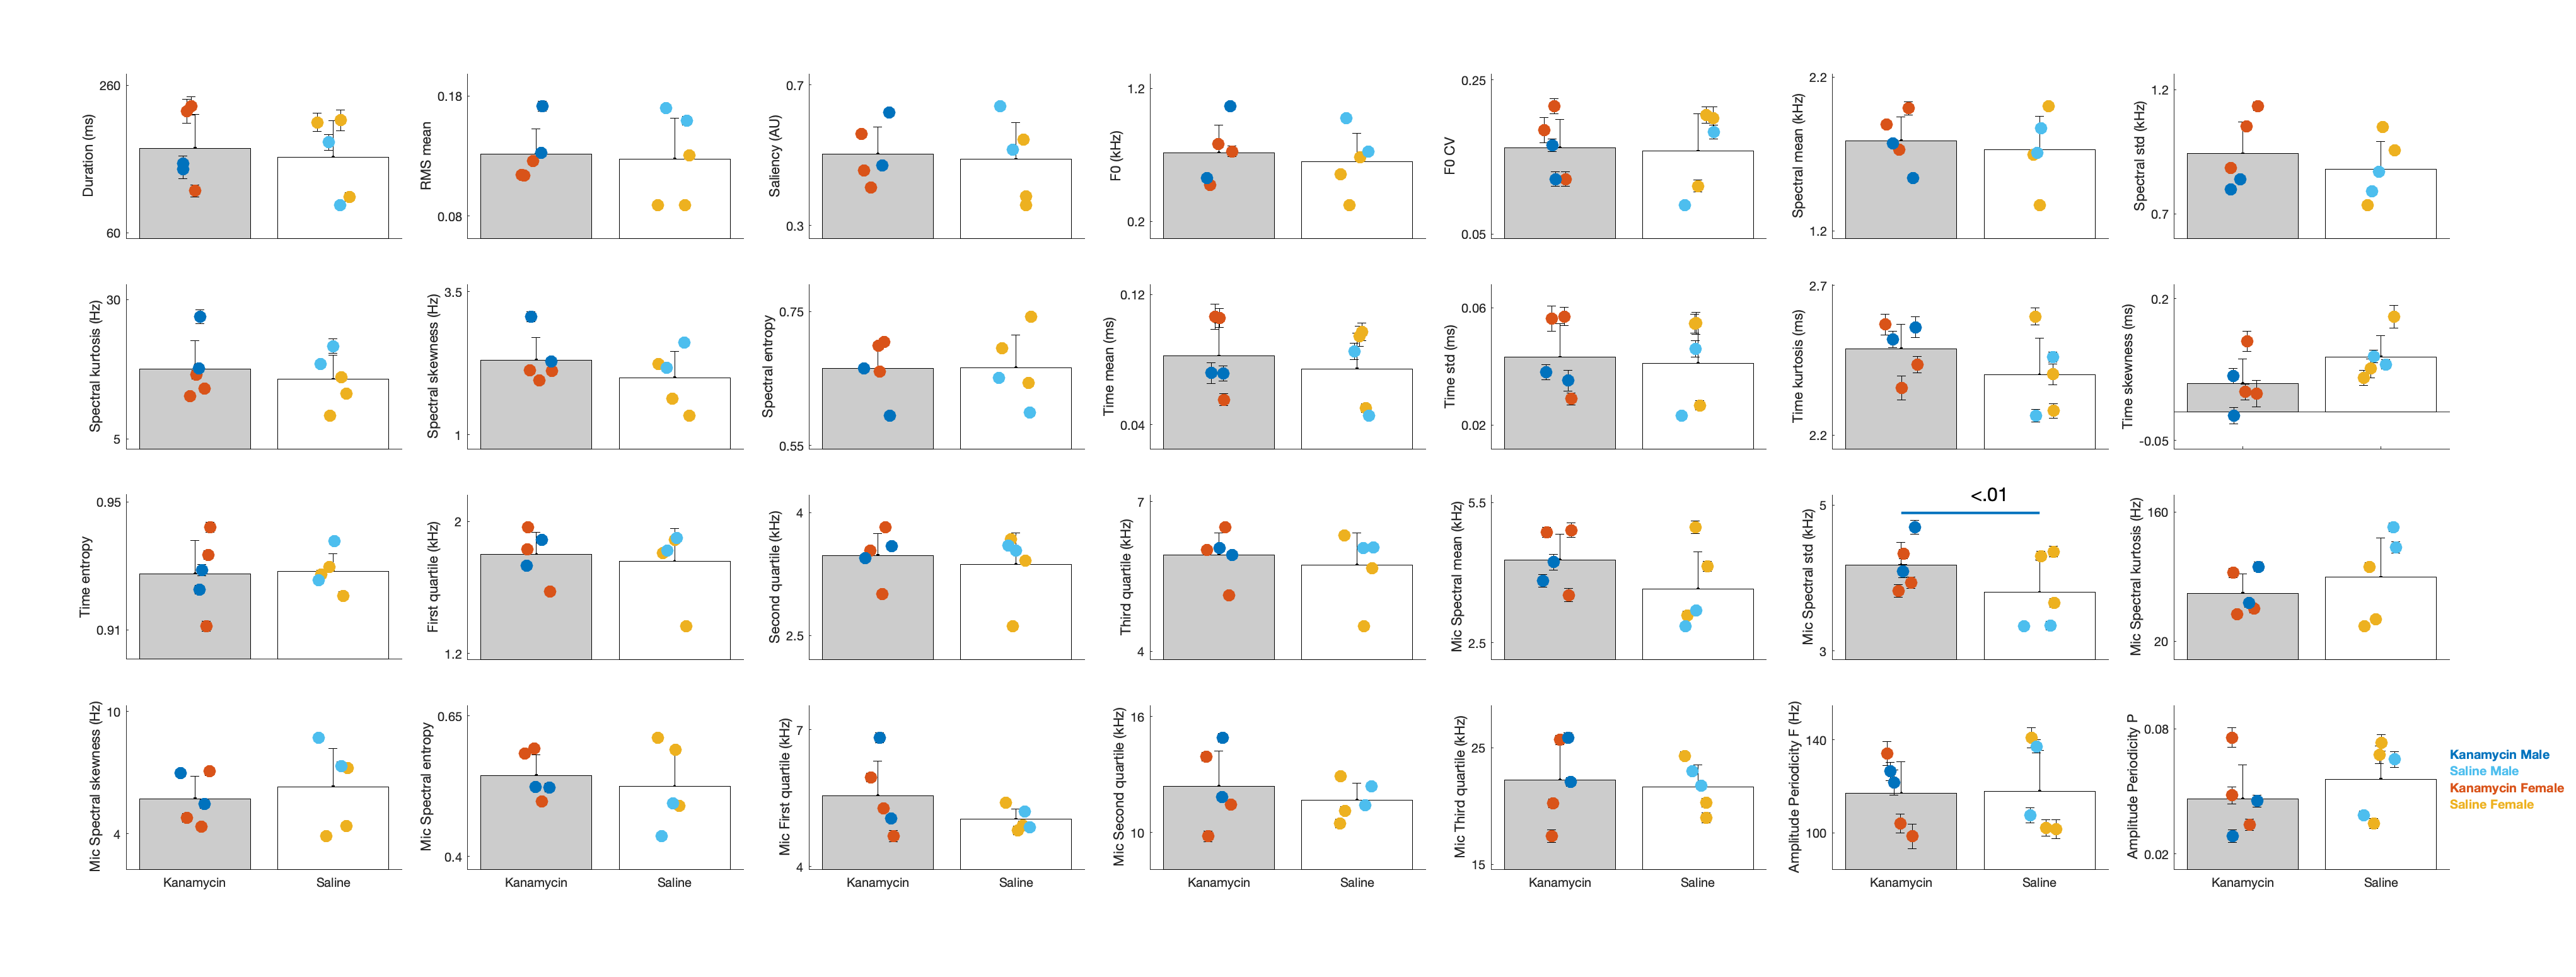

*********************     Calculations on Duration (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue
    lmeR     4     5.1339e+05    5.1342e+05    -2.5669e+05                                
    lme      6     5.1339e+05    5.1344e+05    -2.5669e+05    0.20716    2          0.9016


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat       deltaDF    pValue 
    lme2     5     5.1339e+05    5.1343e+05    -2.5669e+05                                   
    lme      6     5.1339e+05    5.1344e+05    -2.5669e+05    0.0047374    1          0.94513


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    5.1339e+05    5.1344e+05    -2.5669e+05      5.1338e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat        DF       pValue        Lower      Upper 
    {'(Intercept)' }         176.75      25.18       7.0193    36223    2.2695e-12     127.39     226.1
    {'Sex_M'       }        -37.069     39.739     -0.93281    36223       0.35093    -114.96    40.821
    {'HorD_D'      }          14.03     35.644      0.39361    36223       0.69387    -55.834    83.893
    {'Sex_M:HorD_D'}        -3.87

*********************     Calculations on RMS mean   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     4     -78025    -77991    39017                                 
    lme      6     -78023    -77972    39018     2.2002    2          0.33284


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lme2     5     -78023    -77981    39017                                 
    lme      6     -78023    -77972    39018     2.0505    1          0.15216


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -78023    -77972    39018            -78035  

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE           tStat      DF       pValue        Lower         Upper    
    {'(Intercept)' }          0.10285    0.0082855     12.413    36223    2.6134e-35       0.08661      0.11909
    {'Sex_M'       }         0.061986     0.013082     4.7382    36223    2.1644e-06      0.036344     0.087627
    {'HorD_D'      }         0.015097     0.011726     1.2875    36223       0.19792    -0.0078858      0.03808
    {'Sex_M:HorD_D'} 

*********************     Calculations on Saliency (AU)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lmeR     4     -6411.3    -6377.5    3209.7                                 
    lme      6     -6408.1    -6357.3    3210.1    0.78005    2          0.67704


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat     deltaDF    pValue 
    lme2     5     -6409.4    -6367.1    3209.7                                 
    lme      6     -6408.1    -6357.3    3210.1    0.67366    1          0.41178


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           34906
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -6408.1    -6357.3    3210.1           -6420.1 

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat       DF       pValue        Lower        Upper  
    {'(Intercept)' }          0.42828    0.041417      10.341    34902    5.0085e-25       0.3471    0.50946
    {'Sex_M'       }          0.14924    0.065457      2.2799    34902      0.022619     0.020938    0.27753
    {'HorD_D'      }         0.046286    0.058586     0.79005    34902       0.42951    -0.068545    0.16112
    {'Sex_M:HorD_D'}        -

*********************     Calculations on F0 (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     4     49432    49465    -24712                                
    lme      6     49435    49485    -24711    1.0474    2          0.59234


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme2     5     49434    49475    -24712                                 
    lme      6     49435    49485    -24711    0.73955    1          0.38981


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           31743
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    49435    49485    -24711           49423   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat       DF       pValue        Lower       Upper  
    {'(Intercept)' }          0.5183    0.099996      5.1833    31739    2.1938e-07     0.32231     0.7143
    {'Sex_M'       }         0.33122     0.15803       2.096    31739      0.036094    0.021479    0.64096
    {'HorD_D'      }         0.14194     0.14145      1.0035    31739       0.31564    -0.13531     0.4192
    {'Sex_M:HorD_D'}        -0.19587     0.22

*********************     Calculations on F0 CV   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat      deltaDF    pValue 
    lmeR     4     2677.9    2711.4    -1334.9                                  
    lme      6     2681.8      2732    -1334.9    0.050319    2          0.97515


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue
    lme2     5     2679.9    2721.7    -1334.9                                
    lme      6     2681.8      2732    -1334.9    0.01962    1          0.8886


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           31742
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC     LogLikelihood    Deviance
    2681.8    2732    -1334.9          2669.8  

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat       DF       pValue        Lower        Upper   
    {'(Intercept)' }          0.17241    0.022863      7.5408    31738    4.7946e-14      0.12759     0.21722
    {'Sex_M'       }         -0.03766    0.036072      -1.044    31738       0.29648     -0.10836    0.033042
    {'HorD_D'      }        0.0015209     0.03237    0.046983    31738       0.96253    -0.061926    0.064968
    {'Sex_M:HorD_D'}        0.007

*********************     Calculations on Spectral mean (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     4     51174    51208    -25583                                
    lme      6     51176    51227    -25582    2.1181    2          0.34679


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lme2     5     51176    51219    -25583                                
    lme      6     51176    51227    -25582    1.8904    1          0.16916


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    51176    51227    -25582           51164   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF       pValue        Lower        Upper  
    {'(Intercept)' }          1.6904    0.097086     17.412    36223    1.2689e-67       1.5001     1.8807
    {'Sex_M'       }        0.096228     0.15345    0.62709    36223        0.5306     -0.20454      0.397
    {'HorD_D'      }         0.18141     0.13733      1.321    36223        0.1865    -0.087749    0.45057
    {'Sex_M:HorD_D'}        -0.31314     0.21

*********************     Calculations on Spectral std (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat    deltaDF    pValue 
    lmeR     4      787.9    821.89    -389.95                                
    lme      6     790.01    840.99       -389    1.8942    2          0.38787


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lme2     5     788.94    831.43    -389.47                                 
    lme      6     790.01    840.99       -389    0.93696    1          0.33306


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    790.01    840.99    -389             778.01  

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat       DF       pValue        Lower        Upper   
    {'(Intercept)' }          0.91284    0.054347      16.796    36223    4.4942e-63      0.80632      1.0194
    {'Sex_M'       }        -0.083687    0.085906    -0.97418    36223       0.32998     -0.25207    0.084691
    {'HorD_D'      }          0.11071     0.07687      1.4403    36223        0.1498    -0.039954     0.26138
    {'Sex_M:HorD_D'}         

*********************     Calculations on Spectral kurtosis (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue 
    lmeR     4     3.3059e+05    3.3063e+05    -1.6529e+05                                
    lme      6      3.306e+05    3.3065e+05    -1.6529e+05    1.078     2          0.58333


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat      deltaDF    pValue
    lme2     5     3.3059e+05    3.3064e+05    -1.6529e+05                                 
    lme      6      3.306e+05    3.3065e+05    -1.6529e+05    0.026911    1          0.8697


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC          BIC           LogLikelihood    Deviance  
    3.306e+05    3.3065e+05    -1.6529e+05      3.3058e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF       pValue        Lower      Upper 
    {'(Intercept)' }         12.737     1.6302     7.8131    36223    5.7283e-15     9.5417    15.932
    {'Sex_M'       }         7.2954     2.5701     2.8385    36223     0.0045345     2.2579    12.333
    {'HorD_D'      }          1.641     2.3088    0.71077    36223       0.47723    -2.8843    6.1663
    {'Sex_M:HorD_D'}        0.59777     3.6

*********************     Calculations on Spectral skewness (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue
    lmeR     4     1.3673e+05    1.3677e+05    -68363                               
    lme      6     1.3674e+05    1.3679e+05    -68362    2.4993    2          0.2866


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat      deltaDF    pValue
    lme2     5     1.3673e+05    1.3678e+05    -68362                                 
    lme      6     1.3674e+05    1.3679e+05    -68362    0.015068    1          0.9023


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.3674e+05    1.3679e+05    -68362           1.3672e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE         tStat      DF       pValue        Lower       Upper  
    {'(Intercept)' }           1.7342    0.16851     10.291    36223    8.3359e-25      1.4039     2.0645
    {'Sex_M'       }          0.65514     0.2661      2.462    36223       0.01382     0.13358     1.1767
    {'HorD_D'      }          0.32858    0.23846     1.3779    36223       0.16824    -0.13882    0.79597
    {'Sex_M:HorD_D'}     

*********************     Calculations on Spectral entropy   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat      deltaDF    pValue 
    lmeR     4     -54352    -54318    27180                                   
    lme      6     -54348    -54297    27180     0.072414    2          0.96444


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat      deltaDF    pValue 
    lme2     5     -54350    -54307    27180                                   
    lme      6     -54348    -54297    27180     0.066822    1          0.79602


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -54348    -54297    27180            -54360  

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat       DF       pValue         Lower        Upper    
    {'(Intercept)' }          0.69387    0.018088      38.361    36223    1.2382e-315      0.65842      0.72933
    {'Sex_M'       }        -0.068919    0.028583     -2.4112    36223       0.015906     -0.12494    -0.012895
    {'HorD_D'      }        -0.005679    0.025587    -0.22195    36223        0.82436    -0.055831     0.044473
    {'Sex_M:HorD_D'} 

*********************     Calculations on Time mean (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat     deltaDF    pValue 
    lmeR     4     -42835    -42801    21421                                  
    lme      6     -42831    -42780    21422     0.39112    2          0.82237


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat       deltaDF    pValue 
    lme2     5     -42833    -42791    21422                                    
    lme      6     -42831    -42780    21422     0.0072874    1          0.93197


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -42831    -42780    21422            -42843  

Fixed effects coefficients (95% CIs):
    Name                    Estimate      SE          tStat       DF       pValue        Lower        Upper   
    {'(Intercept)' }          0.080334    0.011369      7.0658    36223    1.6261e-12     0.058049     0.10262
    {'Sex_M'       }          -0.01519    0.017941    -0.84668    36223       0.39718    -0.050355    0.019975
    {'HorD_D'      }         0.0086633    0.016095     0.53827    36223        0.5904    -0.022883     0.04021
    {'Sex_M:HorD_D'}     

*********************     Calculations on Time std (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat      deltaDF    pValue 
    lmeR     4     -83978    -83944    41993                                   
    lme      6     -83974    -83923    41993     0.081623    2          0.96001


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat        deltaDF    pValue 
    lme2     5     -83976    -83934    41993                                     
    lme      6     -83974    -83923    41993     5.4949e-06    1          0.99813


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -83974    -83923    41993            -83986  

Fixed effects coefficients (95% CIs):
    Name                    Estimate      SE           tStat        DF       pValue        Lower        Upper   
    {'(Intercept)' }          0.045328    0.0065898       6.8785    36223    6.1487e-12     0.032411    0.058244
    {'Sex_M'       }         -0.010771       0.0104      -1.0357    36223       0.30036    -0.031154    0.009613
    {'HorD_D'      }         0.0020525    0.0093283      0.22003    36223       0.82585    -0.016231    0.020336
    {'Sex_M:HorD_

*********************     Calculations on Time kurtosis (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     4     88748    88782    -44370                                
    lme      6     88749    88800    -44368    2.9794    2          0.22544


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue
    lme2     5     88748    88791    -44369                               
    lme      6     88749    88800    -44368    1.3205    1          0.2505


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    88749    88800    -44368           88737   

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat       DF       pValue     Lower        Upper  
    {'(Intercept)' }           2.4262    0.055947      43.365    36223          0       2.3165     2.5358
    {'Sex_M'       }        -0.063509    0.088187    -0.72016    36223    0.47143     -0.23636    0.10934
    {'HorD_D'      }         0.028309    0.079244     0.35724    36223    0.72092     -0.12701    0.18363
    {'Sex_M:HorD_D'}          0.14834     0.12497

*********************     Calculations on Time skewness (ms)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat    deltaDF    pValue 
    lmeR     4     39418    39452    -19705                                
    lme      6     39419    39470    -19703    3.3866    2          0.18391


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lme2     5     39417    39459    -19703                                 
    lme      6     39419    39470    -19703    0.27272    1          0.60152


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    39419    39470    -19703           39407   

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE          tStat       DF       pValue        Lower        Upper   
    {'(Intercept)' }          0.10154     0.02217      4.5803    36223    4.6593e-06      0.05809       0.145
    {'Sex_M'       }         -0.01023    0.034877    -0.29333    36223       0.76927     -0.07859    0.058129
    {'HorD_D'      }        -0.036428    0.031431      -1.159    36223       0.24648    -0.098034    0.025179
    {'Sex_M:HorD_D'}        -0.02

*********************     Calculations on Time entropy   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC            BIC            LogLik    LRStat     deltaDF    pValue 
    lmeR     4     -1.3088e+05    -1.3084e+05    65442                                  
    lme      6     -1.3087e+05    -1.3082e+05    65442     0.74608    2          0.68864


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC            BIC            LogLik    LRStat     deltaDF    pValue 
    lme2     5     -1.3087e+05    -1.3083e+05    65442                                  
    lme      6     -1.3087e+05    -1.3082e+05    65442     0.73079    1          0.39263


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36227
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC            BIC            LogLikelihood    Deviance   
    -1.3087e+05    -1.3082e+05    65442            -1.3088e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE           tStat      DF       pValue     Lower         Upper   
    {'(Intercept)' }          0.92585    0.0046495     199.13    36223          0       0.91674     0.93496
    {'Sex_M'       }        0.0057616    0.0073439    0.78454    36223    0.43273    -0.0086326    0.020156
    {'HorD_D'      }        0.0029701    0.0065789    0.45145    36223    0.65167    -0.0099247    0.015865
    {'Sex_M

*********************     Calculations on First quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lmeR     4     9722.7    9756.7    -4857.3                                 
    lme      6     9725.9    9776.9      -4857    0.73136    2          0.69372


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik     LRStat     deltaDF    pValue 
    lme2     5     9724.5      9767    -4857.3                                 
    lme      6     9725.9    9776.9      -4857    0.56773    1          0.45116


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36223
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    9725.9    9776.9    -4857            9713.9  

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE          tStat      DF       pValue       Lower       Upper  
    {'(Intercept)' }         1.6869     0.091691     18.397    36219    3.047e-75      1.5071     1.8666
    {'Sex_M'       }        0.17552      0.14496     1.2108    36219      0.22597     -0.1086    0.45964
    {'HorD_D'      }        0.10466      0.12968    0.80707    36219      0.41963    -0.14951    0.35883
    {'Sex_M:HorD_D'}        -0.1567      0.20502 

*********************     Calculations on Second quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue 
    lmeR     4     64051    64085    -32022                                 
    lme      6     64054    64105    -32021    0.74709    2          0.68829


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC      BIC      LogLik    LRStat     deltaDF    pValue
    lme2     5     64053    64095    -32021                                
    lme      6     64054    64105    -32021    0.44463    1          0.5049


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36223
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    64054    64105    -32021           64042   

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat       DF       pValue        Lower       Upper  
    {'(Intercept)' }          3.2339    0.17959      18.007    36219    3.5501e-72      2.8819     3.5859
    {'Sex_M'       }         0.33361    0.28391       1.175    36219       0.23999    -0.22287    0.89009
    {'HorD_D'      }         0.21979      0.254     0.86534    36219       0.38686    -0.27805    0.71764
    {'Sex_M:HorD_D'}        -0.27076    0.40155  

*********************     Calculations on Third quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     4     1.0073e+05    1.0076e+05    -50359                                
    lme      6     1.0073e+05    1.0078e+05    -50358    0.7887    2          0.67412


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue
    lme2     5     1.0073e+05    1.0077e+05    -50359                               
    lme      6     1.0073e+05    1.0078e+05    -50358    0.4543    1          0.5003


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36223
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.0073e+05    1.0078e+05    -50358           1.0072e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat       DF       pValue        Lower       Upper  
    {'(Intercept)' }         5.4974     0.29961      18.349    36219    7.3884e-75      4.9102     6.0846
    {'Sex_M'       }        0.57453     0.47365       1.213    36219       0.22514    -0.35384     1.5029
    {'HorD_D'      }         0.3785     0.42374     0.89323    36219       0.37174    -0.45205      1.209
    {'Sex_M:HorD_D'}     

*********************     Calculations on Mic Spectral mean (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC          BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     4     1.383e+05    1.3833e+05    -69144                                
    lme      6     1.383e+05    1.3835e+05    -69142    3.2288    2          0.19901


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC          BIC           LogLik    LRStat     deltaDF    pValue 
    lme2     5     1.383e+05    1.3834e+05    -69143                                 
    lme      6     1.383e+05    1.3835e+05    -69142    0.74104    1          0.38933


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC          BIC           LogLikelihood    Deviance  
    1.383e+05    1.3835e+05    -69142           1.3828e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF       pValue        Lower       Upper    
    {'(Intercept)' }         4.0651     0.32424     12.537    28087    5.8298e-36      3.4296       4.7006
    {'Sex_M'       }        -1.0435     0.51199    -2.0382    28087      0.041542      -2.047    -0.039999
    {'HorD_D'      }        0.36503     0.45887     0.7955    28087       0.42633    -0.53437       1.2644
    {'Sex_M:HorD_D'}   

*********************     Calculations on Mic Spectral std (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue   
    lmeR     4     1.1366e+05     1.137e+05    -56828                                  
    lme      6     1.1366e+05    1.1371e+05    -56822    10.231    2          0.0060024


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue   
    lme2     5     1.1366e+05     1.137e+05    -56826                                  
    lme      6     1.1366e+05    1.1371e+05    -56822    7.9788    1          0.0047328


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.1366e+05    1.1371e+05    -56822           1.1364e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE         tStat       DF       pValue         Lower       Upper   
    {'(Intercept)' }           4.1076    0.14439      28.447    28087    1.6492e-175      3.8245      4.3906
    {'Sex_M'       }         -0.76363    0.22767     -3.3541    28087     0.00079716     -1.2099    -0.31739
    {'HorD_D'      }        -0.075831     0.2045    -0.37081    28087        0.71078    -0.47666       0.325
    {'Sex_M:H

*********************     Calculations on Mic Spectral kurtosis (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue 
    lmeR     4     3.5575e+05    3.5579e+05    -1.7787e+05                                
    lme      6     3.5575e+05     3.558e+05    -1.7787e+05    4.5699    2          0.10178


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue  
    lme2     5     3.5575e+05    3.5579e+05    -1.7787e+05                                 
    lme      6     3.5575e+05     3.558e+05    -1.7787e+05    3.5143    1          0.060841


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC          LogLikelihood    Deviance  
    3.5575e+05    3.558e+05    -1.7787e+05      3.5574e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat      DF       pValue        Lower      Upper  
    {'(Intercept)' }         60.291     12.496     4.8248    28087    1.4091e-06     35.798     84.784
    {'Sex_M'       }         72.269     19.717     3.6652    28087    0.00024756     33.622     110.92
    {'HorD_D'      }         5.7412     17.691    0.32452    28087       0.74554    -28.934     40.417
    {'Sex_M:HorD_D'}        -57.292    

*********************     Calculations on Mic Spectral skewness (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     4     1.6932e+05    1.6935e+05    -84654                                
    lme      6     1.6932e+05    1.6937e+05    -84653    2.3204    2          0.31343


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lme2     5     1.6932e+05    1.6936e+05    -84654                                
    lme      6     1.6932e+05    1.6937e+05    -84653    1.7738    1          0.18291


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.6932e+05    1.6937e+05    -84653           1.6931e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF       pValue        Lower      Upper  
    {'(Intercept)' }         5.1675     0.65613     7.8758    28087    3.5081e-15     3.8815     6.4536
    {'Sex_M'       }         2.8616      1.0364     2.7611    28087     0.0057649    0.83019      4.893
    {'HorD_D'      }        0.22943     0.92838    0.24713    28087       0.80481    -1.5902     2.0491
    {'Sex_M:HorD_D'}        -2.04

*********************     Calculations on Mic Spectral entropy   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     4     -30909    -30876    15459                                 
    lme      6     -30907    -30858    15460     1.9588    2          0.37554


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lme2     5     -30908    -30866    15459                                 
    lme      6     -30907    -30858    15460     1.4411    1          0.22995


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28091
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -30907    -30858    15460            -30919  

Fixed effects coefficients (95% CIs):
    Name                    Estimate      SE          tStat       DF       pValue         Lower        Upper    
    {'(Intercept)' }           0.56355     0.02286      24.653    28087    8.8912e-133      0.51874      0.60836
    {'Sex_M'       }         -0.098101    0.036121     -2.7159    28087      0.0066131      -0.1689    -0.027303
    {'HorD_D'      }        -0.0058507    0.032339    -0.18092    28087        0.85643    -0.069237     0.057536
    {'Sex_M:HorD_

*********************     Calculations on Mic First quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lmeR     4     1.2369e+05    1.2372e+05    -61839                                
    lme      6     1.2369e+05    1.2374e+05    -61837    2.9877    2          0.22451


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat     deltaDF    pValue 
    lme2     5     1.2369e+05    1.2373e+05    -61838                                 
    lme      6     1.2369e+05    1.2374e+05    -61837    0.87871    1          0.34856


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28087
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.2369e+05    1.2374e+05    -61837           1.2367e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE         tStat       DF       pValue        Lower       Upper  
    {'(Intercept)' }           5.0322    0.29803      16.885    28083    1.2035e-63       4.448     5.6163
    {'Sex_M'       }        0.0047553    0.47079    0.010101    28083       0.99194    -0.91801    0.92752
    {'HorD_D'      }          0.26702    0.42169     0.63322    28083        0.5266    -0.55951     1.0935
    {'Sex_M:HorD_D'} 

*********************     Calculations on Mic Second quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue
    lmeR     4     1.7206e+05    1.7209e+05    -86025                               
    lme      6     1.7206e+05    1.7211e+05    -86024    1.2154    2          0.5446


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik    LRStat    deltaDF    pValue 
    lme2     5     1.7206e+05     1.721e+05    -86024                                
    lme      6     1.7206e+05    1.7211e+05    -86024    0.5238    1          0.46923


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28087
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.7206e+05    1.7211e+05    -86024           1.7205e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE         tStat      DF       pValue        Lower      Upper 
    {'(Intercept)' }         11.506     0.75499      15.24    28083    3.1035e-52     10.026    12.986
    {'Sex_M'       }        0.39911      1.1928    0.33461    28083       0.73792    -1.9388     2.737
    {'HorD_D'      }        0.22287      1.0682    0.20864    28083       0.83473    -1.8708    2.3165
    {'Sex_M:HorD_D'}         1.2377  

*********************     Calculations on Mic Third quartile (kHz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat    deltaDF    pValue 
    lmeR     4     2.0599e+05    2.0602e+05    -1.0299e+05                                
    lme      6     2.0599e+05    2.0604e+05    -1.0299e+05    0.4279    2          0.80739


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat     deltaDF    pValue 
    lme2     5     2.0599e+05    2.0603e+05    -1.0299e+05                                 
    lme      6     2.0599e+05    2.0604e+05    -1.0299e+05    0.28593    1          0.59284


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           28087
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    2.0599e+05    2.0604e+05    -1.0299e+05      2.0598e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate     SE        tStat        DF       pValue        Lower      Upper 
    {'(Intercept)' }           21.188    1.3983       15.152    28083    1.1717e-51     18.447    23.929
    {'Sex_M'       }           1.1732    2.2092      0.53106    28083       0.59538    -3.1569    5.5034
    {'HorD_D'      }        -0.086537    1.9784    -0.043741    28083       0.96511    -3.9643    3.7912
    {'Sex_M:HorD_D'}         

*********************     Calculations on Amplitude Periodicity F (Hz)   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat      deltaDF    pValue 
    lmeR     4     4.4988e+05    4.4991e+05    -2.2494e+05                                  
    lme      6     4.4988e+05    4.4994e+05    -2.2494e+05    0.061661    2          0.96964


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC           BIC           LogLik         LRStat      deltaDF    pValue 
    lme2     5     4.4988e+05    4.4992e+05    -2.2494e+05                                  
    lme      6     4.4988e+05    4.4994e+05    -2.2494e+05    0.051727    1          0.82009


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36166
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    4.4988e+05    4.4994e+05    -2.2494e+05      4.4987e+05

Fixed effects coefficients (95% CIs):
    Name                    Estimate    SE        tStat       DF       pValue        Lower      Upper 
    {'(Intercept)' }         114.92     8.5771      13.399    36162    7.6776e-41     98.113    131.74
    {'Sex_M'       }         7.4114     13.523     0.54806    36162       0.58365    -19.094    33.917
    {'HorD_D'      }        -2.6926     12.148    -0.22166    36162       0.82458    -26.502    21.117
    {'Sex_M:HorD_D'}          4.363  

*********************     Calculations on Amplitude Periodicity P   ********************


TestLME_HD =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat    deltaDF    pValue 
    lmeR     4     -65253    -65219    32631                                 
    lme      6     -65251    -65200    32631     1.1381    2          0.56605


TestLME_Int_HorD_Sex =     Theoretical Likelihood Ratio Test

    Model    DF    AIC       BIC       LogLik    LRStat     deltaDF    pValue 
    lme2     5     -65252    -65210    32631                                  
    lme      6     -65251    -65200    32631     0.21606    1          0.64206


lme = Linear mixed-effects model fit by ML

Model information:
    Number of observations           36166
    Fixed effects coefficients           4
    Random effects coefficients         10
    Covariance parameters                2

Formula:
    AcVar ~ 1 + Sex*HorD + (1 | BatID)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -65251    -65200    32631            -65263  

Fixed effects coefficients (95% CIs):
    Name                    Estimate      SE           tStat       DF       pValue        Lower        Upper   
    {'(Intercept)' }          0.058445    0.0087287      6.6957    36162    2.1781e-11     0.041336    0.075553
    {'Sex_M'       }        -0.0065718     0.013777    -0.47703    36162       0.63335    -0.033574    0.020431
    {'HorD_D'      }        -0.0058347     0.012356    -0.47223    36162       0.63677    -0.030052    0.018383
    {'Sex_M:HorD_D'} 

% List of variables
AcVars = Tbl.Properties.VariableNames(5:end);

figure(1)
tiledlayout(4,7)
clf
set(gcf,'Visible','on')
INN = find(MicAudioGood01);

for vv=1:length(AcVars)
    fprintf(1, '*********************     Calculations on %s   ********************\n', AcVars{vv})
    AcVar = Tbl.(sprintf('%s',AcVars{vv}));
    if contains(AcVars{vv}, 'Mic')
        Tbl_local = table(BatID(INN), CallType(INN), Sex(INN),Deaf(INN), AcVar(INN), 'VariableNames', {'BatID', 'CT','Sex','HorD', 'AcVar'});
        Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
    else
        Tbl_local = table(BatID, CallType, Sex,Deaf, AcVar, 'VariableNames', {'BatID', 'CT','Sex','HorD', 'AcVar'});
        Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});
    end
    % Full Model
    lme = fitlme(Tbl_local, 'AcVar ~ Sex * HorD + (1|BatID)');
    % Reduced model without deafening fixed effect
    lmeR = fitlme(Tbl_local, 'AcVar ~ Sex + (1|BatID)');
    TestLME_HD=compare(lmeR, lme)

    lme2 = fitlme(Tbl_local, 'AcVar ~ Sex + HorD + (1|BatID)');
    TestLME_Int_HorD_Sex=compare(lme2, lme)
    lme

    % Nice plot 1
    AcVar_mean_pBat = nan(size(BatName));
    AcVar_se_pBat = nan(size(BatName));
    Col_local = nan(length(BatName),3);
    for bb=1:length(BatName)
        if contains(AcVars{vv}, 'Mic')
            Ind = INN(strcmp(BatID(MicAudioGood01),num2str(BatName(bb))));
        else
            Ind = find(strcmp(BatID,num2str(BatName(bb))));
        end
        AcVar_mean_pBat(bb) = mean(AcVar(Ind), 'omitnan');
        AcVar_se_pBat(bb) = std(AcVar(Ind), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
        Col_local(bb,:) = UCSexDeaf(strcmp(USexDeaf, BatSexDeaf{bb}),:);
    end

    %         AcVar_Male_meanse(1) = mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Male')));
    %         AcVar_Male_meanse(2) = std(AcVar_mean_pBat(contains(BatSexDeaf, 'Male')));
    %         AcVar_Female_meanse(1) = mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Female')));
    %         AcVar_Female_meanse(2) = std(AcVar_mean_pBat(contains(BatSexDeaf, 'Female')));
    %         AcVar_meanse_pBat_sexnorm = nan(length(AcVar_mean_pBat),2);
    %         for bb=1:length(BatName)
    %             if contains(AcVar, 'Mic')
    %                 Ind = INN(strcmp(BatID(MicAudioGood01),num2str(BatName(bb))));
    %             else
    %                 Ind = find(strcmp(BatID,num2str(BatName(bb))));
    %             end
    %             if contains(BatSexDeaf{bb}, 'Male')
    %                 AcVar_meanse_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Male_meanse(1))./AcVar_Male_meanse(2), 'omitnan');
    %                 AcVar_meanse_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Male_meanse(1))./AcVar_Male_meanse(2), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
    %             elseif contains(BatSexDeaf{bb}, 'Female')
    %                 AcVar_meanse_pBat_sexnorm(bb,1) = mean((AcVar(Ind) - AcVar_Female_meanse(1))./AcVar_Female_meanse(2), 'omitnan');
    %                 AcVar_meanse_pBat_sexnorm(bb,2) = std((AcVar(Ind) - AcVar_Female_meanse(1))./AcVar_Female_meanse(2), 'omitnan')/sum(~isnan(AcVar(Ind)))^0.5;
    %             end
    %         end
    AcVarMean_HD = [mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Kanamycin'))) mean(AcVar_mean_pBat(contains(BatSexDeaf, 'Saline')))];
    AcVarSE_HD = [std(AcVar_mean_pBat(contains(BatSexDeaf, 'Kanamycin')))/sum(contains(BatSexDeaf, 'Kanamycin'))^0.5 std(AcVar_mean_pBat(contains(BatSexDeaf, 'Saline')))/sum(contains(BatSexDeaf, 'Saline'))^0.5];
    
    N=nexttile;
    XHorD = ones(size(BatSexDeaf)) + (rand(size(BatSexDeaf))-0.5).*0.5;
    XHorD(contains(BatSexDeaf, 'Saline')) = XHorD(contains(BatSexDeaf, 'Saline'))+2;
    errorbar([1 3],AcVarMean_HD, 2*AcVarSE_HD, 2*AcVarSE_HD, 'k.')
    hold on
    B=bar([1 3], AcVarMean_HD);
    B.FaceColor = 'flat';
    B.CData(1,:) = 0.8*ones(1,3);
    B.CData(2,:) = ones(1,3);
    hold on
    errorbar(XHorD,AcVar_mean_pBat, 2*AcVar_se_pBat, 2*AcVar_se_pBat, 'k.')
    hold on
    scatter(XHorD,AcVar_mean_pBat,100, Col_local, 'filled')
    ylabel(sprintf('%s', AcVars{vv}))
    XLim = [0 4];
    set(gca, 'XLim', XLim);
    MinVal = min(AcVar_mean_pBat);
    MaxVal = max(AcVar_mean_pBat);
    YLim = [MinVal - (MaxVal-MinVal)/3 MaxVal + (MaxVal-MinVal)/3];
    set(gca, 'YLim', YLim)
    if vv==length(AcVars)
        for ct=1:length(USexDeaf)
            text(4,YLim(2)-diff(YLim)*(2+ct)/10, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
        end
    end
    if vv>21
        set(gca, 'XTick', [1 3],'XTickLabel', {'Kanamycin' 'Saline'})
    else
        set(gca, 'XTick', [1 3],'XTickLabel', {'' ''})
    end
    YTick= get(gca, 'YTick');
    set(gca,'YTick', [YTick(1) YTick(end)])
    hold off
    if ~any([TestLME_HD.pValue(2) TestLME_Int_HorD_Sex.pValue(2)] <0.05)
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
%         T.FontWeight = 'normal';
%         T.Color = 0.7.*ones(1,3);
    else
%         T=title(sprintf('pKS = %.3f; pS*KS = %.3f', TestLME_HD.pValue(2),TestLME_Int_HorD_Sex.pValue(2)));
        hold on
        plot([1 3], 19/20*YLim(2).*ones(1,2), '-','Color',UCSexDeaf(1,:), 'LineWidth',2)
        hold on
        text(2,YLim(2), '<.01','FontSize', 15)
    end
    N.Box = 0;
    

    %         nexttile
    %         errorbar(XHorD,AcVar_meanse_pBat_sexnorm(:,1), 2*AcVar_meanse_pBat_sexnorm(:,2), 2*AcVar_meanse_pBat_sexnorm(:,2), 'k.')
    %         hold on
    %         scatter(XHorD,AcVar_meanse_pBat_sexnorm(:,1),100, Col_local, 'filled')
    %         ylabel(sprintf('%s (z-scored)', AcVars{vv}))
    %         XLim = [0 4];
    %         set(gca, 'XLim', XLim);
    %         YLim = get(gca, 'YLim');
    %         for ct=1:length(USexDeaf)
    %             text(diff(XLim)*1/10+XLim(1),YLim(2)-diff(YLim)*(2+ct)/30, USexDeaf(ct), 'Color',UCSexDeaf(ct,:), 'FontWeight','bold' )
    %         end
    %         set(gca,'XTick', [1 3], 'XTickLabel', {'Deaf' 'Hearing'})
    %         hold off
    %         title(sprintf('Values per bat Ac Cluster %d normalized per sex', UCat(cc)))


end